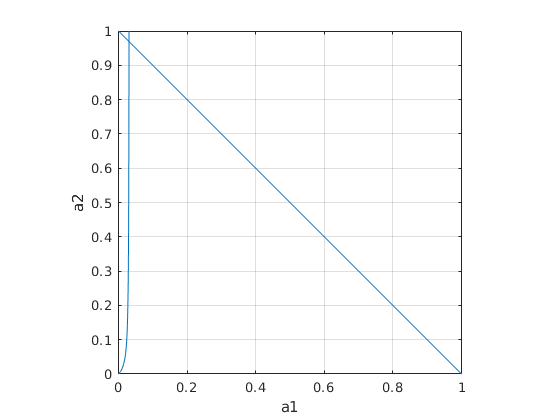

clear

N = 100000 ;
p1 = 0.5 ;
p2 = 1-p1 ;
c = 10 ;

q1 = 0.5 ;
q2 = 1 ;


if q1>=q2
    a1 = -1:0.01:1 ;
    % a2 = ( c*p2*a1 ) ./ ( (q1-q2)*sqrt(N)*a1 + c*p1 ) ;
%     a2 = (c*p2*sqrt(N) + q2-q1 - c*p1*sqrt(N)./(1+a1*N)) ./ ...
%          (N*(q1-q2 + c*p1*sqrt(N)./(1+a1*N))) ;
     a2 = ((1+a1*N)*(q2-q1) + c*sqrt(N)*(p2-p1) + c*p2*a1*N^(3/2)) ./ ...
          ((N+a1*N^2)*(q1-q2) + c*p1*(N)^(3/2)) ;
else
    a2 = -1:0.01:1 ;
    a1 = ((1+a2*N)*(q1-q2) + c*sqrt(N)*(p1-p2) + c*p1*a2*N^(3/2)) ./ ...
         ((N+a2*N^2)*(q2-q1) + c*p2*(N)^(3/2)) ;
end

figure
box on
grid on
hold on
plot(a1, a2)
line([0, 1], [1, 0])
hold off
axis equal
xlim([0,1])
ylim([0,1])
xlabel('a1')
ylabel('a2')

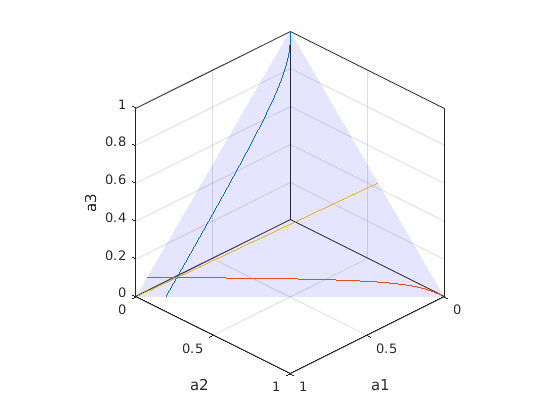

clear

N = 91000 ;

c = 40 ;

p1 = 0.3 ;
p2 = 0.4 ;
p3 = 1-p1-p2 ;

q1 = 1 ;
q2 = 0.5 ;
q3 = 0.5 ;

% comptue border fore each pair of variables
figure
box on
grid on
hold on
min = 0 ;
max = 1 ;
step = 0.01 ;
% border 1-2
if q1>=q2
    a1 = min:step:max ;
    b12 = border(a1, 1, 2, N, c, q1, q2, q3, p1, p2, p3);
    plot3(a1, b12, ones(size(a1))-a1-b12, "LineWidth",1)
else
    a2 = min:step:max ;
    b21 = border(a2, 2, 1, N, c, q1, q2, q3, p1, p2, p3);
    plot3(b21, a2, ones(size(a2))-a2-b21, "LineWidth",1)
end
% border 1-3
if q1>=q3
    a1 = min:step:max ;
    b13 = border(a1, 1, 3, N, c, q1, q2, q3, p1, p2, p3);
    plot3(a1, ones(size(a1))-a1-b13, b13, "LineWidth",1)
else
    a3 = min:step:max ;
    b31 = border(a3, 3, 1, N, c, q1, q2, q3, p1, p2, p3);
    plot3(b31, ones(size(a3))-a3-b31, a3, "LineWidth",1)
end
% border 2-3
if q2>=q3
    a2 = min:step:max ;
    b23 = border(a2, 2, 3, N, c, q1, q2, q3, p1, p2, p3);
    plot3(ones(size(a2))-a2-b23, a2, b23, "LineWidth",1)
else
    a3 = min:step:max ;
    b32 = border(a3, 3, 2, N, c, q1, q2, q3, p1, p2, p3);
    plot3(ones(size(a3))-a3-b32, b32, a3, "LineWidth",1)
end

% plane
[X, Y]= meshgrid(0:0.1:1, 0:0.1:1) ;
surf(X, Y, ones(size(X))-X-Y, "EdgeColor","none", "FaceAlpha",0.1, "FaceColor",[0,0,1])
hold off
axis equal
xlabel("a1")
ylabel("a2")
zlabel("a3")
xlim([0,1])
ylim([0,1]) 
zlim([0,1])
view(135, 30)

clear

syms a1 c N q1 q2 p1 p2 f

f = simplify(((1+a1*N)*(q2-q1) + c*sqrt(N)*(p2-p1) + c*p2*a1*N^(3/2)) ./ ...
    ((N+a1*N^2)*(q1-q2) + c*p1*(N)^(3/2)) )

$$f = -\frac{\left(N\,a_{1}+1\right)\,\left(q_{1}-q_{2}\right)+\sqrt{N}\,c\,\left(p_{1}-p_{2}\right)-N^{3/2}\,a_{1}\,c\,p_{2}}{\left(a_{1}\,N^{2}+N\right)\,\left(q_{1}-q_{2}\right)+N^{3/2}\,c\,p_{1}}$$


% pretty(simplify(f))

clear

syms a1 c N q1 q2 q3 p1 p2 p3 f

f = simplify( ...
    1-a1 ...
    - ((1+a1*N)*(q1-q2)+c*sqrt(N)*(p1-p2)-a1*c*p2*N^(3/2))/(N*((1+a1*N)*(q2-q1)-c*sqrt(N)*p1)) ...
    - ((1+a1*N)*(q1-q3)+c*sqrt(N)*(p1-p3)-a1*c*p3*N^(3/2))/(N*((1+a1*N)*(q3-q1)-c*sqrt(N)*p1)) ...
    )

$$f = \begin{array}{l} \frac{\sigma_{2}+\sqrt{N}\,c\,\left(p_{1}-p_{2}\right)-N^{3/2}\,a_{1}\,c\,p_{2}}{N\,\left(\sigma_{2}+\sqrt{N}\,c\,p_{1}\right)}-a_{1}+\frac{\sigma_{1}+\sqrt{N}\,c\,\left(p_{1}-p_{3}\right)-N^{3/2}\,a_{1}\,c\,p_{3}}{N\,\left(\sigma_{1}+\sqrt{N}\,c\,p_{1}\right)}+1\\ \mathrm{where}\\ \sigma_{1}=\left(N\,a_{1}+1\right)\,\left(q_{1}-q_{3}\right)\\ \sigma_{2}=\left(N\,a_{1}+1\right)\,\left(q_{1}-q_{2}\right) \end{array}$$

clear 
syms a1 a2 a3 q1 q2 q3 p1 p2 p3 c N d e

% eq1 = (q1 + c*p1/(a1^d*N^e) == q2 + c*p2/(a2^d*N^e)) ;
% eq2 = (q1 + c*p1/(a1^d*N^e) == q3 + c*p3/(a3^d*N^e)) ;
% eq3 = (a1 + a2 + a3 == 1) ;
% simplify(solve(eq1, a2))

eq1 = (a2 == a1*c*p2/(a1*sqrt(N)*(q1-q2)+c*p1) ) ;
eq2 = (a3 == a1*c*p3/(a1*sqrt(N)*(q1-q3)+c*p1) ) ;
eq3 = (a1 + a2 + a3 == 1) ;
f = solve(eq1, eq2, eq3, a1, a2, a3)

f = struct with fields:
    a1: [3×1 sym]
    a2: [3×1 sym]
    a3: [3×1 sym]


Simulate convergence

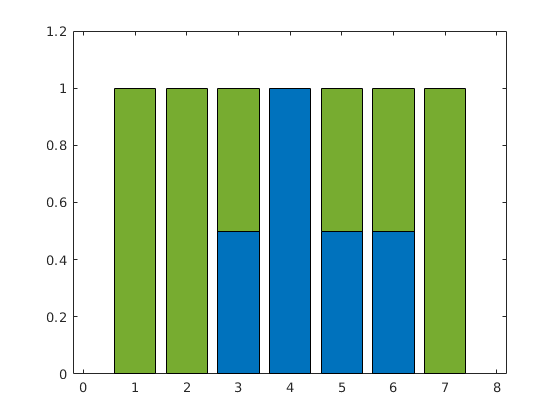

rng(11)

M = 7 ;
P = ones(1,M)/M ;
% P = normalize(rand(1, M), "norm" , 1) ;
c = 1 ;
N = zeros(1,M) ;
Q_conv = randi([0 2],  [1, M])/2 ;
Q = 0.5*ones(1,M) ;
U = Q + c*P*sqrt(sum(N))./(1+N) ;

for n = 1:1e7
    % choose action
    [~, i] = max(U) ;
    
    % update count
    N(i) = N(i) + 1 ;
    
    % update value estimate
    Q(i) = Q(i) + (Q_conv(i)-Q(i))/N(i) ;
    
    % update UCB
    U = Q + c*P*sqrt(sum(N))./(1+N) ;
end

% visualize UCB
figure
box on
hold on
bar(U, 'FaceColor', [0.4660 0.6740 0.1880])
bar(Q, 'FaceColor', [0 0.4470 0.7410])
hold off


alpha = N / sum(N) ;

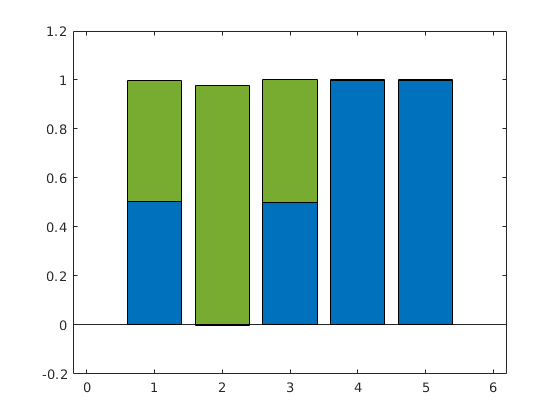

rng(11)

numsim = 1e6 ;

M = 5 ;
% P = ones(1,M)/M ;
P = normalize(rand(1, M), "norm" , 1) ;
c = 1 ;
N = zeros(1,M) ;
Q_conv_mu = randi([0 2],  [1,M])/2 ;
Q_conv_std = 0.1*rand([1,M]) ;
Q = 0.5*ones(1,M) ;
U = Q + c*P*sqrt(sum(N))./(1+N) ;

q_all = zeros(M, numsim) ;

for n = 1:numsim
    % choose action
    [~, i] = max(U) ;
    
    % update count
    N(i) = N(i) + 1 ;
    
    % update value estimate
    r = Q_conv_mu(i) + Q_conv_std(i)*randn ;
    Q(i) = Q(i) + (r-Q(i))/N(i) ;
    
    % keep track of Q-values
    q_all(:,n) = Q' ;
    
    % update UCB
    U = Q + c*P*sqrt(sum(N))./(1+N) ;
end

% visualize UCB
figure
box on
hold on
bar(U, 'FaceColor', [0.4660 0.6740 0.1880])
bar(Q, 'FaceColor', [0 0.4470 0.7410])
hold off

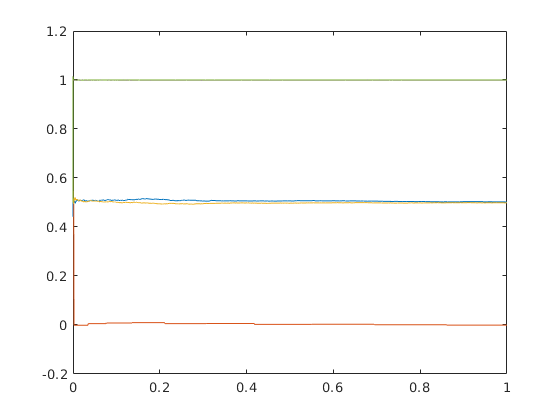


figure
box on
hold on
for m = 1:M
    plot(linspace(0,1,numsim), q_all(m,:))
end
hold off


alpha = N / sum(N) ;

clear all
clc

syms ai N Qi Qj c Pi Pj f

% f = (ai*(N*(Qj-Qi) + c*Pj*N^(3/2)) + (Qj-Qi) + c*N^(1/2)*(Pj-Pi)) / ...
%       (ai*N^2*(Qi-Qj) + N*(Qi-Qj) + c*Pi*N^(1/2) ) ;

f = ((1+ai*N)*(Qj-Qi) + c*sqrt(N)*(Pj-Pi) + c*Pj*ai*N^(3/2)) / ...
    ((N+ai*N^2)*(Qi-Qj) + c*Pi*(N)^(3/2) ) ;

df_dai = diff( f, ai ) ;
df_dN = diff( f, N ) ;

disp("derrivative to ai")

derrivative to ai


pretty(simplify(df_dai))

          2
(N Pi Pj c )/(Qi - Qj + N Qi ai

                            2
   - N Qj ai + sqrt(N) Pi c)




disp("derrivative to N")

derrivative to N


pretty(simplify(df_dN))

/ /
| | (Qi - Qj) (2 N ai + 1)
\ \

     3 sqrt(N) Pi c \
   + -------------- | ((Qi - Qj)
            2       /

   (N ai + 1) + sqrt(N) c (Pi - Pj)

      3/2          \   2
   - N    Pj ai c) |/#1
                   /

     /                c (Pi - Pj)
   - | ai (Qi - Qj) + -----------
     \                 2 sqrt(N)

     3 sqrt(N) Pj ai c \
   - ----------------- |/#1
             2         /

where

              2
   #1 == (ai N  + N) (Qi - Qj)

         3/2
      + N    Pi c




clear all
clc

syms ai aj P_i P_j N dvi dvj

dvi = P_i * (sqrt(N+1)/(2+ai*N) - sqrt(N)/(1+ai*N)) ;
dvj = P_j * (sqrt(N+1)/(1+aj*N) - sqrt(N)/(1+aj*N)) ;

simplify(limit( dvi/dvj, N, Inf))

$$ans = \frac{P_{i}\,\mathrm{aj}\,\left(\mathrm{ai}-2\right)}{P_{j}\,{\mathrm{ai}}^{2}}$$


simplify(limit( diff(dvi,N) / diff(dvj,N), N, Inf))

$$ans = \frac{P_{i}\,\mathrm{aj}\,\left(\mathrm{ai}-2\right)}{P_{j}\,{\mathrm{ai}}^{2}}$$


% dvi_dN = diff(dvi, N) ;
% dvj_dN = diff(dvj, N) ;
% 
% disp("derrivative of dvi")
% pretty(simplify(dvi_dN))
% 
% disp("derrivative of dvj")
% pretty(simplify(dvj_dN))

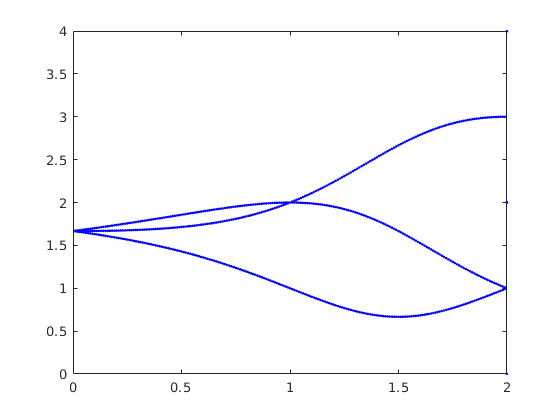

r1 = 1 ;
r2 = 2 ;

% b = .25 ;
% x = (b*r2*((1-b)^2+(1-b)) + b*r1)/(1-(1-b)^3)

min = 0 ;
max = 2 ;
step = 0.01 ;
N = floor((max-min)/step) ;

conv = cell(1,N) ;

for n = 1:N
        
    b = min + n*step ;
    x = rand ;

    M = 500 ;
    path = zeros(1,3*M) ;
    for m = 1:3:3*M
        
        x = (1-b)*x + b*r2 ;    
        path(m) = x ;
        
        x = (1-b)*x + b*r2 ;
        path(m+1) = x ;
        
        x = (1-b)*x + b*r1 ;
        path(m+2) = x ;
    end
    
    conv(n) = { unique(path(end-50:end)) } ;
end

figure
box on
hold on
for n = 1:N
    eqs = conv{n} ;
    for i = 1:length(eqs)
        plot(min + n*step, eqs(i), 'b.')
    end
end
hold off

function aj = border(ai, i, j, N, c, q1, q2, q3, p1, p2, p3)

    % process input
    if i == 1
        qi = q1 ;
        pi = p1 ;
    elseif i == 2
        qi = q2 ;
        pi = p2 ;
    elseif i == 3
        qi = q3 ;
        pi = p3 ;
    end
    
    if j == 1
        qj = q1 ;
        pj = p1 ;
    elseif j == 2
        qj = q2 ;
        pj = p2 ;
    elseif j == 3
        qj = q3 ;
        pj = p3 ;
    end 
    
    aj = ((1+ai*N)*(qi-qj) + c*sqrt(N)*(pi-pj) - c*pj*ai*N^(3/2)) ./ ...
          ((N+ai*N^2)*(qj-qi) - c*pi*(N)^(3/2)) ;
end